# Short term trading strategy

Clear variables

clear;
clc;
tic

Load data

% m = matfile("pricevolumedata.mat","Writable",true) ;
loadDataInput

dataInput = struct with fields:
    closepriceTT: [960×665 timetable]
     highpriceTT: [960×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [960×665 timetable]
     openpriceTT: [960×665 timetable]
        volumeTT: [960×665 timetable]


Test data and parameters

% Test objective and constraints function
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

paramsInput =     70   106     5     3     8    14   107    29     4     4     6


% paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

optimPoint = 10;
tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;

% [portDailyRetTT, netDailyRetperSymTT] will be used further in the
% optimization section

[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

analyzeTradeResults

portEndValue = 1.8863e+04

portMinValue = 0.9184

portMaxValue = 1.9312e+04

MaxDD = 0.1392

MaxDDIndex =    502
   513


drawdownDate = 2×1 datetime array
   2019-12-02
   2019-12-17


sharpeRatio = 4.9784

FortValueAtOptPoint = 1.6747e+04

PortRetOptPtEnd = 0.1264

optimPointDate = datetime
   2021-10-07


nYear = 3.8164

CAGR = 12.1922

dailyRetAvg = 0.0109

dailyRetMin = -0.1234

dailyRetMax = 0.3212

symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'TCPI'}       {[1.5249]}    
    {'INAF'}       {[1.4762]}    
    {'BNBA'}       {[1.3930]}    
    {'BBHI'}       {[1.3901]}    
    {'KAEF'}       {[1.3480]}    
    {'FIRE'}       {[1.3460]}    
    {'ACST'}       {[1.3167]}    
    {'ABBA'}       {[1.3013]}    
    {'BOLA'}       {[1.2735]}    
    {'SURE'}       {[1.2349]}    
    {'FILM'}       {[1.2328]}    
    {'BBYB'}       {[1.2278]}    
    {'ZBRA'}       {[1.2217]}    
    {'MPPA'}       {[1.2209]}    
    {'BABP'}       {[1.2092]}    
    {'DEAL'}       {[1.2039]}    



stockpicks

stockPick = 3×2 table
     symbol     TradingSignal
    ________    _____________

    {'BBHI'}        {[1]}    
    {'MLPT'}        {[1]}    
    {'PANR'}        {[1]}    


Optimize parameters

startTime = uint64
2589467420749

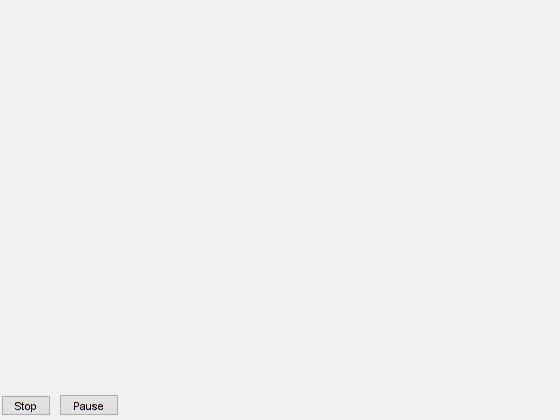

Error using isappdata
Value must be a handle.

Error in callAllOptimPlotFcns (line 97)
    if isappdata(fig,'data')

Error in globaloptim.bmo.BlackboxModelOptimizer/outputAndPlots (

optimParams_v4

Statistics and Analysis

Examine result of optimized params

paramsInput     = sol
tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;


Analyze results statistics

analyzeTradeResults 


Stock Picks

% Stock picks
stockpicks

Analyze the input parameters compared to its boundaries

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
counterhelp     = [1    2   3   4   5   6   7   8   9   10  11]
sol
lb              = [20   50  5   1   3   2   80  10  1   1   0] 
ub              = [150  150 60  6   20  30  250 60  10  8   15] 


End

toc